# Varables de la máquina.

## 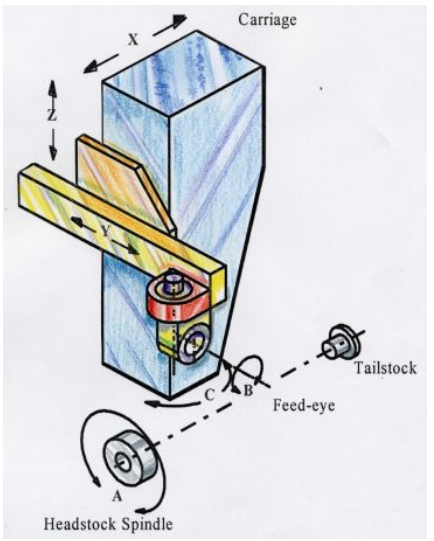

## Posiciones de referencia

- **RefA:** Posición de referencia del eje A

- **RefX:** Posición de referencia del eje X

- **RefY:** Posición de referencia del eje Y

- **RefB:** Posición de referencia del eje B

- **RefZ:** Posición de referencia del eje Z

- **RefC:** Posición de referencia del eje C

## Dimensiones

- **Xmin:** Valor mínimo de X.

- **Xmax:** Valor máximo de X.

- **Ymin:** Valor mínimo de Y.

- **Ymax:** Valor máximo de Y.

- **Zmin:** Valor mínimo de Z.

- **Zmax:** Valor máximo de Z.

- **Cmin:** Valor mínimo de C.

- **Cmax:** Valor máximo de C.

- **POew:** Ancho del ojal de salida.

- **POe:** Excentricidad del ojal de salida.

- **YawR: **radio de guiñada.

## Velocidades

- **VA:** Velocidad máxima de A en revoluciones/min.

- **VX:** Velocidad máxima de X en m/s.

- **VY:** Velocidad máxima de Y en m/s.

- **VB:** Velocidad máxima de B en revoluciones/min.

- **VZ:** Velocidad máxima de Z en m/s.

- **VC:** Velocidad máxima de C en revoluciones/min.

##  Aceleraciones: definidas como el cambio de velocidad máximo permitido de un eje entre dos registros de datos de control

- **AA: **Aceleración máxima de A en revoluciones/min.

- **AX:** Aceleración máxima de X en m/s.

- **AY:** Aceleración máxima de Y en m/s.

- **AB:** Aceleración máxima de B en revoluciones/min.

- **AZ: **Aceleración máxima de Z en m/s.

- **AC:** Aceleración máxima de C en revoluciones/min.

## Resoluciones

- **RA:** resolución del eje de A en inc/revolución.

- **RX:** resolución del eje X en inc/mm.

- **RY:** resolución del eje Y en inc/mm.

- **RB:** resolución del eje de B en inc/revolución.

- **RZ:** resolución del eje Z en inc/mm.

- **RC:** resolución del eje de C en inc/revolución.

function vector_variables_de_la_maquina = variables_de_la_maquina(excel)
    vector_variables_de_la_maquina = struct();
        vector_variables_de_la_maquina.RefA = 0;
        vector_variables_de_la_maquina.RefX = 0;
        vector_variables_de_la_maquina.RefY = 260;
        vector_variables_de_la_maquina.RefB = 0;
        vector_variables_de_la_maquina.RefZ = 0;
        vector_variables_de_la_maquina.RefC = 0;
        vector_variables_de_la_maquina.Xmin = 165.15; %mm
        vector_variables_de_la_maquina.Xmax = 2644.7; %mm
        vector_variables_de_la_maquina.Ymin = -120;   %mm
        vector_variables_de_la_maquina.Ymax = 311;    %mm
        vector_variables_de_la_maquina.Zmin = 0;      %mm
        vector_variables_de_la_maquina.Zmax = 364;    %mm
        vector_variables_de_la_maquina.Cmin = -50;    %º
        vector_variables_de_la_maquina.Cmax = 50;     %º
        vector_variables_de_la_maquina.POew = 50;     %mm
        vector_variables_de_la_maquina.POe = 0;       %mm
        vector_variables_de_la_maquina.YawR = 260;    %mm
        vector_variables_de_la_maquina.VA = 150;      %360º/min
        vector_variables_de_la_maquina.VX = 1;        %m/s
        vector_variables_de_la_maquina.VY = 0.5;      %m/s
        vector_variables_de_la_maquina.VB = 115;      %360º/min
        vector_variables_de_la_maquina.VZ = 0.5;      %m/s
        vector_variables_de_la_maquina.VC = 100;      %360º/min
        vector_variables_de_la_maquina.AA = 8;        %360º/min
        vector_variables_de_la_maquina.AX = 4;        %m/s
        vector_variables_de_la_maquina.AY = 30;       %m/s
        vector_variables_de_la_maquina.AB = 60;       %360º/min
        vector_variables_de_la_maquina.AZ = 1;        %m/s
        vector_variables_de_la_maquina.AC = 45;       %360º/min
        vector_variables_de_la_maquina.RA = 360;      %inc/360º
        vector_variables_de_la_maquina.RX = 1;        %inc/mm
        vector_variables_de_la_maquina.RY = -1;       %inc/mm
        vector_variables_de_la_maquina.RB = 360;      %inc/360º
        vector_variables_de_la_maquina.RZ = 1;        %inc/mm
        vector_variables_de_la_maquina.RC = 360;      %inc/360º
        vector_variables_de_la_maquina.minproc = 0.03;
    %Velocidades Máximas - inc/s
    vector_variables_de_la_maquina.VAmax = abs (vector_variables_de_la_maquina.VA * vector_variables_de_la_maquina.RA / 60);
    vector_variables_de_la_maquina.VXmax = abs (vector_variables_de_la_maquina.VX * 1000 * vector_variables_de_la_maquina.RX);
    vector_variables_de_la_maquina.VYmax = abs (vector_variables_de_la_maquina.VY * 1000 * vector_variables_de_la_maquina.RY);
    vector_variables_de_la_maquina.VBmax = abs (vector_variables_de_la_maquina.VB * vector_variables_de_la_maquina.RB / 60);
    vector_variables_de_la_maquina.VZmax = abs (vector_variables_de_la_maquina.VZ * 1000 * vector_variables_de_la_maquina.RZ);
    vector_variables_de_la_maquina.VCmax = abs (vector_variables_de_la_maquina.VC * vector_variables_de_la_maquina.RC / 60);
    %Aceleraciones máximas
    vector_variables_de_la_maquina.AAmax = abs (vector_variables_de_la_maquina.AA * vector_variables_de_la_maquina.RA);
    vector_variables_de_la_maquina.AXmax = abs (vector_variables_de_la_maquina.AX * 60 * 1000 * vector_variables_de_la_maquina.RX);
    vector_variables_de_la_maquina.AYmax = abs (vector_variables_de_la_maquina.AY * 60 * 1000 * vector_variables_de_la_maquina.RY);
    vector_variables_de_la_maquina.ABmax = abs (vector_variables_de_la_maquina.AB * vector_variables_de_la_maquina.RB);
    vector_variables_de_la_maquina.AZmax = abs (vector_variables_de_la_maquina.AZ * 60 * 1000 * vector_variables_de_la_maquina.RZ);
    vector_variables_de_la_maquina.ACmax = abs (vector_variables_de_la_maquina.AC * vector_variables_de_la_maquina.RC);
    % Escribir una celda, ya que es más fácil exportar un archivo con formato de celdas
    celda_variables_de_la_maquina(1, :) = {'RefA', vector_variables_de_la_maquina.RefA};
    celda_variables_de_la_maquina(2, :) = {'RefX', vector_variables_de_la_maquina.RefX};
    celda_variables_de_la_maquina(3, :) = {'RefY', vector_variables_de_la_maquina.RefY};
    celda_variables_de_la_maquina(4, :) = {'RefB', vector_variables_de_la_maquina.RefB};
    celda_variables_de_la_maquina(5, :) = {'RefZ', vector_variables_de_la_maquina.RefZ};
    celda_variables_de_la_maquina(6, :) = {'RefC', vector_variables_de_la_maquina.RefC};
    celda_variables_de_la_maquina(7, :) = {'Xmin', vector_variables_de_la_maquina.Xmin};
    celda_variables_de_la_maquina(8, :) = {'Xmax', vector_variables_de_la_maquina.Xmax};
    celda_variables_de_la_maquina(9, :) = {'Ymin', vector_variables_de_la_maquina.Ymin};
    celda_variables_de_la_maquina(10, :) = {'Ymax', vector_variables_de_la_maquina.Ymax};
    celda_variables_de_la_maquina(11, :) = {'Zmin', vector_variables_de_la_maquina.Zmin};
    celda_variables_de_la_maquina(12, :) = {'Zmax,', vector_variables_de_la_maquina.Zmax,};
    celda_variables_de_la_maquina(13, :) = {'Cmin', vector_variables_de_la_maquina.Cmin};
    celda_variables_de_la_maquina(14, :) = {'Cmax', vector_variables_de_la_maquina.Cmax};
    celda_variables_de_la_maquina(15, :) = {'POew', vector_variables_de_la_maquina.POew};
    celda_variables_de_la_maquina(16, :) = {'POe', vector_variables_de_la_maquina.POe};
    celda_variables_de_la_maquina(17, :) = {'YawR', vector_variables_de_la_maquina.YawR};
    celda_variables_de_la_maquina(18, :) = {'VA', vector_variables_de_la_maquina.VA};
    celda_variables_de_la_maquina(19, :) = {'VX', vector_variables_de_la_maquina.VX};
    celda_variables_de_la_maquina(20, :) = {'VY', vector_variables_de_la_maquina.VY};
    celda_variables_de_la_maquina(21, :) = {'VB', vector_variables_de_la_maquina.VB};
    celda_variables_de_la_maquina(22, :) = {'VZ', vector_variables_de_la_maquina.VZ};
    celda_variables_de_la_maquina(23, :) = {'VC', vector_variables_de_la_maquina.VC};
    celda_variables_de_la_maquina(24, :) = {'AA', vector_variables_de_la_maquina.AA};
    celda_variables_de_la_maquina(25, :) = {'AX', vector_variables_de_la_maquina.AX};
    celda_variables_de_la_maquina(26, :) = {'AY', vector_variables_de_la_maquina.AY};
    celda_variables_de_la_maquina(27, :) = {'AB', vector_variables_de_la_maquina.AB};
    celda_variables_de_la_maquina(28, :) = {'AZ', vector_variables_de_la_maquina.AZ};
    celda_variables_de_la_maquina(29, :) = {'AC', vector_variables_de_la_maquina.AC};
    celda_variables_de_la_maquina(30, :) = {'RA', vector_variables_de_la_maquina.RA};
    celda_variables_de_la_maquina(31, :) = {'RX', vector_variables_de_la_maquina.RX};
    celda_variables_de_la_maquina(32, :) = {'RY', vector_variables_de_la_maquina.RY};
    celda_variables_de_la_maquina(33, :) = {'RB', vector_variables_de_la_maquina.RB};
    celda_variables_de_la_maquina(34, :) = {'RZ', vector_variables_de_la_maquina.RZ};
    celda_variables_de_la_maquina(35, :) = {'RC', vector_variables_de_la_maquina.RC};
    celda_variables_de_la_maquina(36, :) = {'minproc', vector_variables_de_la_maquina.minproc};
    celda_variables_de_la_maquina(37, :) = {'VAmax', vector_variables_de_la_maquina.VAmax};
    celda_variables_de_la_maquina(38, :) = {'VXmax', vector_variables_de_la_maquina.VXmax};
    celda_variables_de_la_maquina(39, :) = {'VYmax', vector_variables_de_la_maquina.VYmax};
    celda_variables_de_la_maquina(40, :) = {'VBmax', vector_variables_de_la_maquina.VBmax};
    celda_variables_de_la_maquina(41, :) = {'VZmax', vector_variables_de_la_maquina.VZmax};
    celda_variables_de_la_maquina(42, :) = {'VCmax', vector_variables_de_la_maquina.VCmax};
    celda_variables_de_la_maquina(43, :) = {'AAmax', vector_variables_de_la_maquina.AAmax};
    celda_variables_de_la_maquina(44, :) = {'AXmax', vector_variables_de_la_maquina.AXmax};
    celda_variables_de_la_maquina(45, :) = {'AYmax', vector_variables_de_la_maquina.AYmax};
    celda_variables_de_la_maquina(46, :) = {'ABmax', vector_variables_de_la_maquina.ABmax};
    celda_variables_de_la_maquina(47, :) = {'AZmax', vector_variables_de_la_maquina.AZmax};
    celda_variables_de_la_maquina(48, :) = {'ACmax', vector_variables_de_la_maquina.ACmax};
    % Escribir un archivo con las variables de entrada
    writecell(celda_variables_de_la_maquina, excel, 'Sheet', 'Variables de la maquina', 'Range', 'A1');
end